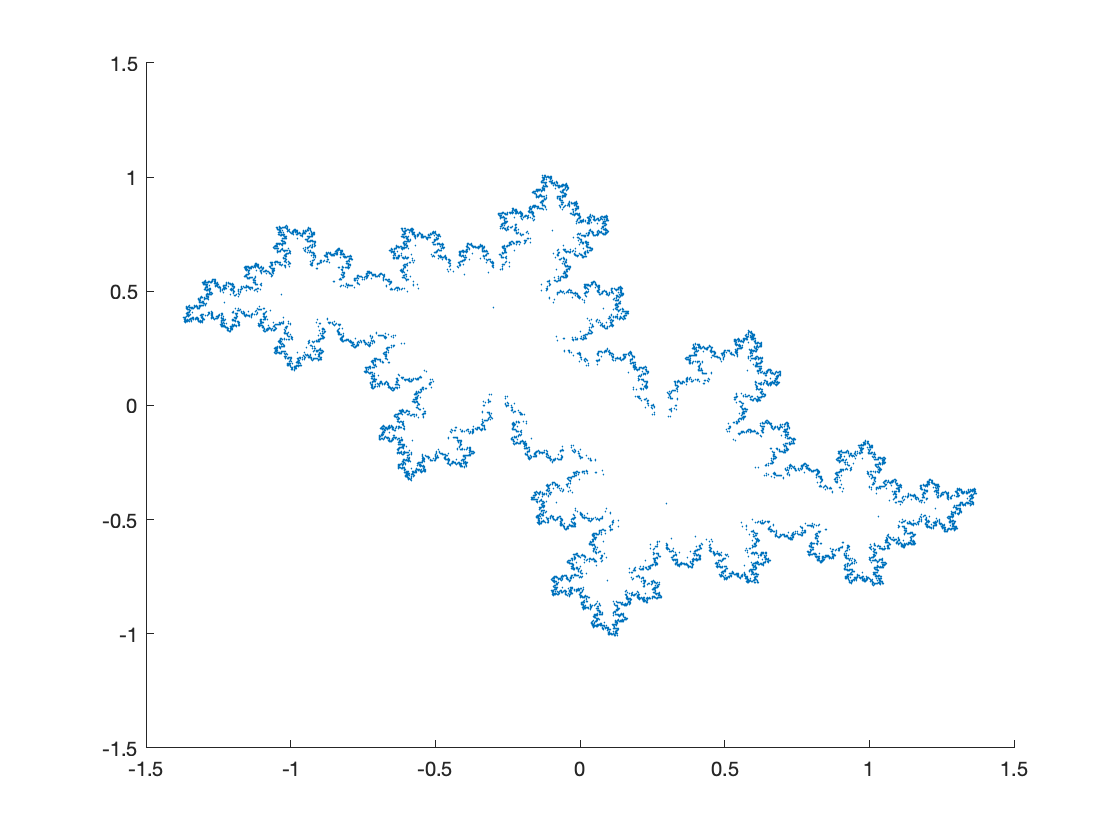

juliasimple(-0.365 + 0.627i, 24)

Plots the julia set for any given complex value for c. 

function output = juliasimple(c, depth)
    
    f = @(z) sqrt(z - c);
    out_list = -0.25 + 0.5i;

    for j = 1:depth
        val = f(out_list);
        out_list = [val -val];
    end

    scatter(real(out_list), imag(out_list), 1, 'filled')

end